# Multi-link pendulum system: Simscape modeling

Input system parameters:

init_angle=90   % Initial angle from vertical (degrees)

init_angle = 90

n_links=2       % Number of links 

n_links = 2


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=1;     % Damping factor at joints (N*m/(deg/s))
spring=0.1;    % Torsional spring constant (N*m/deg)

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

% Simulate model
simout = sim("pendulum_system.slx");

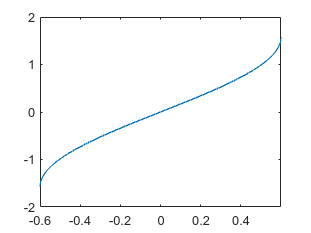

pendulum_angle = reshape(simout.pendulum_angle(1,1,:),[],1);

end_x = reshape(simout.end_x(1,1,:),[],1);
end_y = reshape(simout.end_y(1,1,:),[],1);
end_z = reshape(simout.end_z(1,1,:),[],1);
end_rotation = reshape(simout.end_axis(2,1,:),[],1);

plot(end_x,end_rotation)